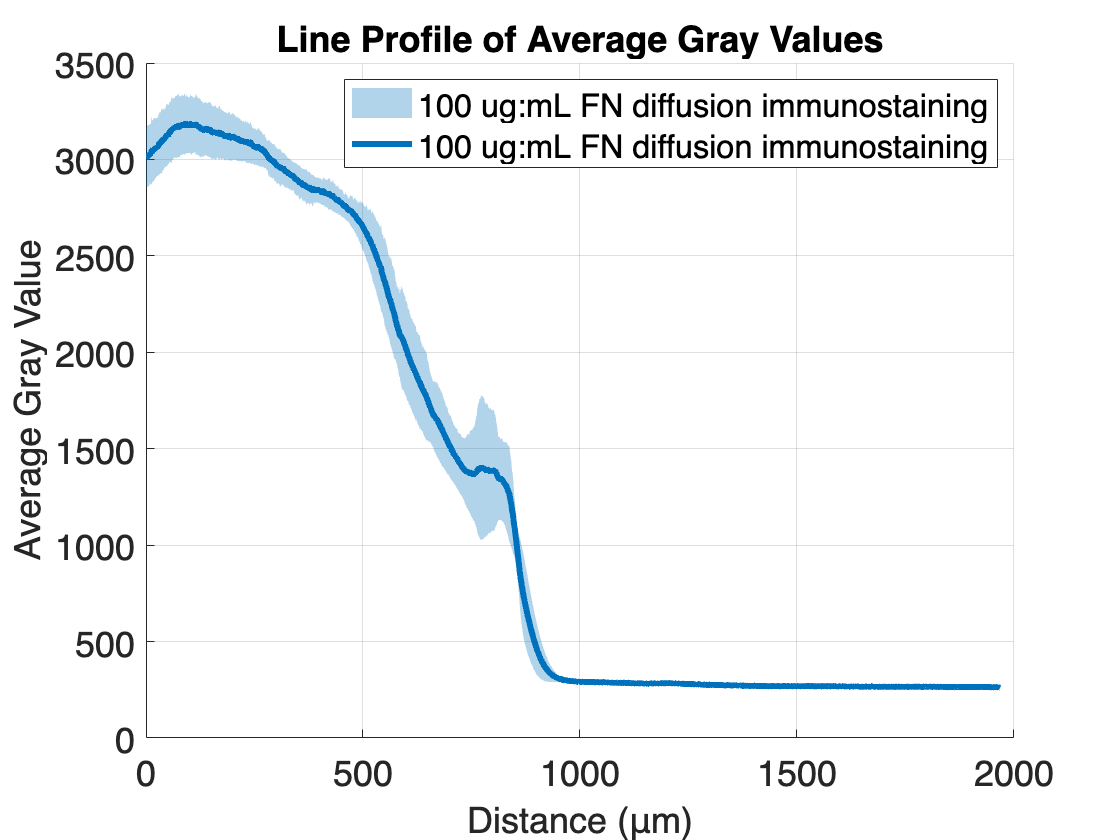

clc
clear all;
close all; 

% Ask the user if there are multiple groups for comparison
answer = input('Do you have multiple groups for comparison? (yes/no): ', 's');
compare_groups = strcmpi(answer, 'yes');

if compare_groups
    % Ask how many groups are there
    num_groups = input('How many groups are you comparing?: ');
else
    num_groups = 1;
end

% Initialize cell arrays to store data for each group
group_data = cell(1, num_groups);

for group = 1:num_groups
    % Ask the user to select the folder containing the ROI files for each group
    folder_path = uigetdir('', ['Select the folder for Group ' num2str(group)]);

    % Check if the user clicked Cancel
    if folder_path == 0
        error(['Folder selection canceled for Group ' num2str(group) ' by the user.']);
    end

    % Get a list of all CSV files in the selected folder
    roi_files = dir(fullfile(folder_path, '*.csv'));

    % Initialize variables for average and std calculations for each group
    gray_values = cell(1, length(roi_files));
    locations = cell(1, length(roi_files));

    % Load data from each CSV file
    for i = 1:length(roi_files)
        file_path = fullfile(folder_path, roi_files(i).name);
        data = csvread(file_path, 1, 0);
        gray_values{i} = data(:, 2);
        locations{i} = data(:, 1);
    end

    % Find the common set of locations
    common_locations = locations{1};
    for i = 2:length(roi_files)
        common_locations = intersect(common_locations, locations{i});
    end

    % Initialize variables for average and std calculations
    average_gray_values = zeros(length(common_locations), 1);
    std_values = zeros(length(common_locations), 1);

    % Calculate average and std for each group
    for i = 1:length(common_locations)
        loc = common_locations(i);
        gray_vals_at_loc = [];

        % Concatenate gray values for the current location across all files in the group
        for j = 1:length(roi_files)
            gray_vals_at_loc = [gray_vals_at_loc; gray_values{j}(locations{j} == loc)];
        end

        % Calculate average and std for the current location
        average_gray_values(i) = mean(gray_vals_at_loc);
        std_values(i) = std(gray_vals_at_loc);
    end

    % Store the data for each group
    group_data{group}.common_locations = common_locations;
    group_data{group}.average_gray_values = average_gray_values;
    group_data{group}.std_values = std_values;
    group_data{group}.folder_name = roi_files(1).folder;
end

remove_std_shading = input('Do you want to remove standard deviation shading? (yes/no): ', 's');
remove_std_shading = strcmpi(remove_std_shading, 'yes');

% Plot the line profiles for each group with shading
figure;
hold on; 
xlabel('Distance (μm)');
ylabel('Average Gray Value');
title('Line Profile of Average Gray Values');
grid on;
fontsize(18, 'points');

for group = 1:num_groups
    % Extract only the folder name from the path
    [~, folder_name, ~] = fileparts(group_data{group}.folder_name);

    % Calculate upper and lower bounds for the shaded area
    upper_bound = group_data{group}.average_gray_values + group_data{group}.std_values;
    lower_bound = group_data{group}.average_gray_values - group_data{group}.std_values;

    % Create x and y data for the shaded area
    x_fill = [group_data{group}.common_locations; flipud(group_data{group}.common_locations)];
    y_fill = [upper_bound; flipud(lower_bound)];

    % Use the same color for shading as the average line
    color_order = get(gca, 'ColorOrder');
    line_color = color_order(mod(group - 1, size(color_order, 1)) + 1, :);

    if ~remove_std_shading
        % Fill the shaded area between the two std lines with the same color as the average line
        alpha_value = 0.3; % Adjust the transparency of the shaded area
        fill(x_fill, y_fill, line_color, 'EdgeColor', 'none', 'FaceAlpha', alpha_value,'DisplayName', folder_name);
    end

    % Plot the average gray values on top with the same color as the shading
    plot(group_data{group}.common_locations, group_data{group}.average_gray_values, 'LineWidth', 3, 'Color', line_color, 'DisplayName', folder_name);
end

legend('show');

% Set the y-axis lower limit to 0 for all groups
yl = ylim; % Get current limits.
ylim([0, yl(2)]); % Replace lower limit only with a y of 0.

% Optionally, you can save the plot as an image
saveas(gcf, 'line_profile_with_shading_multiple_groups.png');